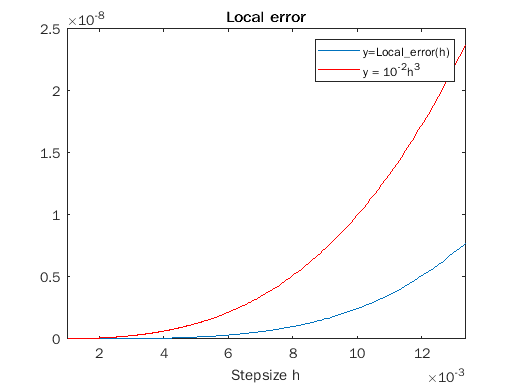

a = 0;
b = 1;



j = 1;
init_n = 75;
final_n = 1000;
h_vect = zeros(final_n - init_n + 1,1);
local_error = zeros(final_n - init_n + 1,1);
global_error = zeros(final_n - init_n + 1,1);

for n = init_n:final_n
    h = (b-a)/n;
    
    y = zeros(n+1,1);
    y(1) = 1;
    y(2) = exp(-h);
    y(3) = exp(-2*h);
    
    for i = 4:n+1
        y(i) = (-3/2) *y(i-1)+3*y(i-2) - (1/2)*y(i-3) -3*h*y(i-1);
    end
    
    h_vect(j) = h;
    local_error(j) = exp(-3*h)-y(4);
    global_error(j) = abs(y(n+1));
    
    j = j+1;
end

figure
plot(h_vect,local_error,'DisplayName','y=Local\_error(h)')
hold on 
plot(h_vect,10^(-2)*h_vect.^3,'r','DisplayName','y = 10^{-2}h^3')
title('Local error')
xlabel('Stepsize h')
xlim([h_vect(end),h_vect(1)])
legend

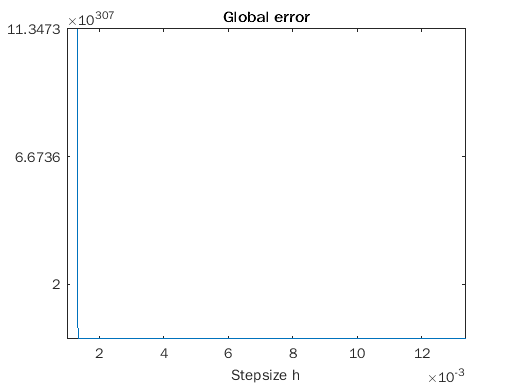


figure
plot(h_vect,global_error)
title('Global error')
xlabel('Stepsize h')
xlim([h_vect(end),h_vect(1)])